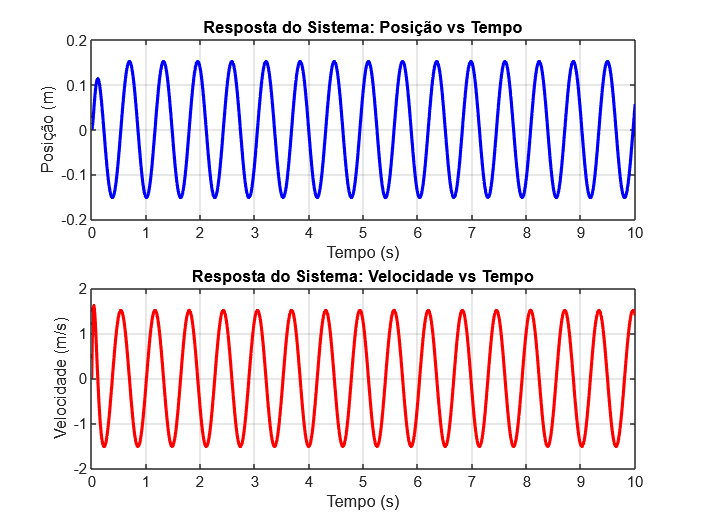


    % Este código resolve uma EDO não homogênea de 2ª ordem com condições iniciais
    
    %% Definição do Problema
    % Exemplo: Sistema massa-mola-amortecedor forçado
    % m*y'' + c*y' + k*y = F(t)
    % Com condições iniciais y(0) = y0, y'(0) = v0
    
    %% Parâmetros do Sistema (MODIFIQUE ESTES VALORES)
    s = 1;      % massa (kg)
    b = 40;      % coeficiente de amortecimento (N.s/m)
    c = 625;      % constante da mola (N/m)
    
    %% Condições Iniciais (MODIFIQUE ESTES VALORES)
    y0 = 0;   % posição inicial (m)
    v0 = 0;     % velocidade inicial (m/s)
    
    %% Forçamento Externo (FUNÇÃO NÃO HOMOGÊNEA - MODIFIQUE CONFORME NECESSÁRIO)
    % Escolha uma das opções abaixo (descomente a desejada):
    
    % 1. Degrau unitário a partir de t=2
    % F = @(t) 2*(t >= 0);
    
    % 2. Força senoidal
     F = @(t) 100*cos(10*t);
    
    % 3. Força exponencial decrescente
    % F = @(t) 4*exp(-0.5*t);
    
    % 4. Pulso retangular entre t=1 e t=3
    % F = @(t) 1.5*(t >= 1 & t <= 3);
    
    %% Intervalo de Tempo para Simulação
    tspan = 0:0.01:10; % de 0 a 10 segundos
    
    %% Resolução da EDO
    % Converter a EDO de 2ª ordem para um sistema de EDOs de 1ª ordem
    % Definimos:
    % Y(1) = y (posição)
    % Y(2) = y' (velocidade)
    
    % Função que define o sistema de EDOs
    odefun = @(t,Y) [Y(2);                     % y' = velocidade
                    (F(t) - b*Y(2) - c*Y(1))]; % y'' = (F(t) - c*y' - k*y)/m
    
    % Condições iniciais no formato [y(0); y'(0)]
    Y0 = [y0; v0];
    
    % Resolver usando ode45
    [t, Y] = ode45(odefun, tspan, Y0);
    
    %% Visualização dos Resultados
    figure;
    
    % Gráfico da Posição
    subplot(2,1,1);
    plot(t, Y(:,1), 'b-', 'LineWidth', 2);
    xlabel('Tempo (s)');
    ylabel('Posição (m)');
    title('Resposta do Sistema: Posição vs Tempo');
    grid on;
    
    % Gráfico da Velocidade
    subplot(2,1,2);
    plot(t, Y(:,2), 'r-', 'LineWidth', 2);
    xlabel('Tempo (s)');
    ylabel('Velocidade (m/s)');
    title('Resposta do Sistema: Velocidade vs Tempo');
    grid on;

    
    %% Exibição da Equação Resolvida
    fprintf('\nEDO resolvida:\n');


EDO resolvida:


    fprintf('%g*y'''' + %g*y'' + %g*y = F(t)\n\n', s,b,c);

1*y'' + 40*y' + 625*y = F(t)



    fprintf('Condições iniciais:\n');

Condições iniciais:


    fprintf('y(0) = %g\n', y0);

y(0) = 0


    fprintf('y''(0) = %g\n\n', v0);

y'(0) = 0



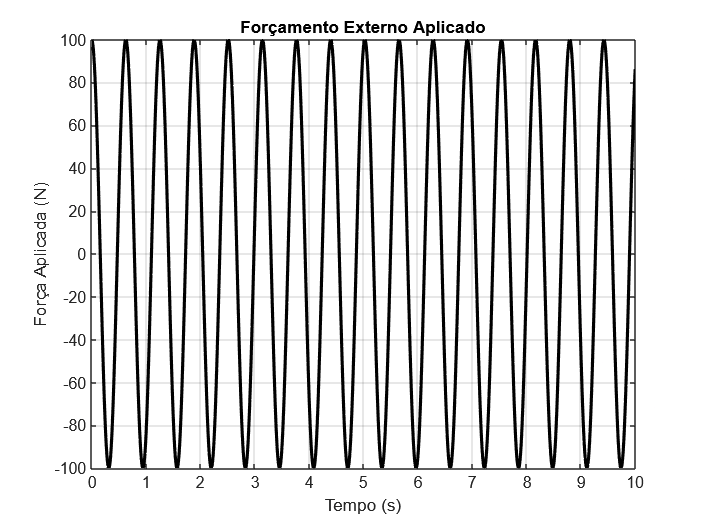

    
    % Plot adicional da força aplicada
    figure;
    f_values = arrayfun(F, t);
    plot(t, f_values, 'k-', 'LineWidth', 2);
    xlabel('Tempo (s)');
    ylabel('Força Aplicada (N)');
    title('Forçamento Externo Aplicado');
    grid on;

resultado de gabs

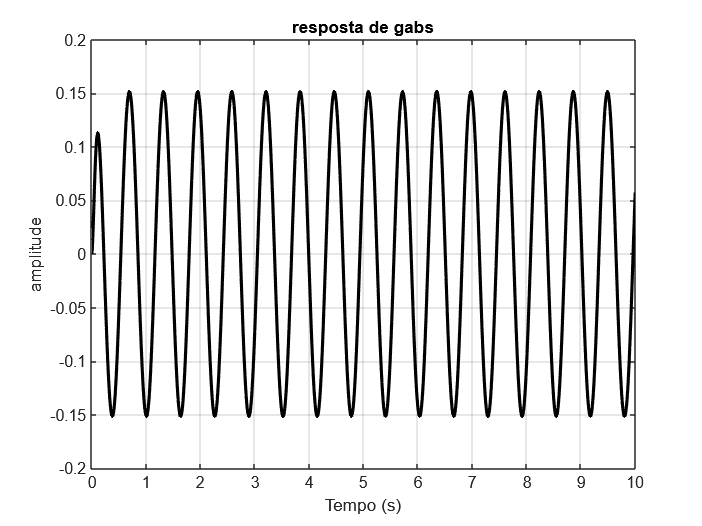

     % Plot adicional da força aplicada
    figure;
    gabs = (4/697)*((exp(-20*t))/3*(-63*cos(15*t)-116*sin(15*t)) + 21*cos(10*t) + 16*sin(10*t));
    plot(t, gabs, 'k-', 'LineWidth', 2);
    xlabel('Tempo (s)');
    ylabel('amplitude');
    title('resposta de gabs');
    grid on;